# USER PARAMETERS

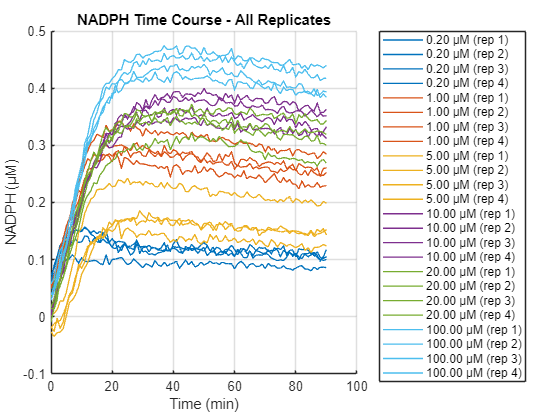

close all, clear
filename                = 'MichaelisMenten.xlsx';   % Path/filename
sheet                   = 'drDH7_NADPH(NADP)';    % Sheet name
replicateCount          = 4;                        % # replicate columns per concentration
num_pts_for_initial_slope =20;                      % # of time points to use for initial slope
enzyme_pmol             = 1.0975;                   % pmol enzyme in the reaction
reactionVolume_mL       = 0.1;                      % reaction volume in mL
alpha                   = 0.05;                     % for 95% CI

%% 1) READ EXCEL DATA
rawData = readmatrix(filename, 'Sheet', sheet);
if isempty(rawData)
    error('No numeric data found in sheet "%s" of "%s".', sheet, filename);
end

% Expected layout:
%   row 1, columns 2..end: substrate concentration (µM)
%   col 1, rows 2..end:    time (min)
%   rows 2..end, cols 2..end: NADPH data (µM)

concentrations_in_header = rawData(1, 2:end);   % 1 x totalColumns
time                     = rawData(2:end, 1);   % (N x 1) in minutes
NADPHData                = rawData(2:end, 2:end); % (N x totalColumns) in µM

[numTimePoints, numDataCols] = size(NADPHData);

if numTimePoints < num_pts_for_initial_slope
    error(['Not enough time points (%d) to fit the first %d points. ' ...
           'Increase # of rows or decrease num_pts_for_initial_slope.'], ...
           numTimePoints, num_pts_for_initial_slope);
end
if mod(numDataCols, replicateCount) ~= 0
    error(['Total data columns (%d) is not divisible by replicateCount (%d). ' ...
           'Check your file layout or replicateCount.'], ...
           numDataCols, replicateCount);
end

% # of distinct substrate concentrations
numConcs = numDataCols / replicateCount;

%% 2) PLOT ALL REPLICATES (TIME VS NADPH) & COMPUTE INITIAL SLOPES
figure('Name','NADPH Time Course - All Replicates');
hold on;
colors = lines(numConcs);

% We'll store initial rates & substrate concentrations for the M-M fit
all_v0_converted = [];
all_Conc         = [];

% We'll also store the R² values for each replicate's initial slope fit
replicateR2      = zeros(1, numConcs * replicateCount);  
r2Idx = 1;

idx = 1;
for c = 1:numConcs
    colStart  = (c-1)*replicateCount + 1;
    colEnd    = c*replicateCount;
    theseCols = colStart:colEnd;
    
    thisColor = colors(c,:);
    
    for r = 1:replicateCount
        repCol    = theseCols(r);
        singleRep = NADPHData(:, repCol);
        
        concValue = concentrations_in_header(repCol);  % µM for that replicate
        
        % Plot entire time course
        plot(time, singleRep, 'Color', thisColor, 'LineWidth', 1.0, ...
            'DisplayName', sprintf('%.2f µM (rep %d)', concValue, r));
        
        % Compute initial slope from first few points
        init_t   = time(1:num_pts_for_initial_slope);
        init_f   = singleRep(1:num_pts_for_initial_slope);
        
        % Linear fit
        p = polyfit(init_t, init_f, 1);  % slope (µM/min), intercept
        slope_uM_per_min = p(1);
        
        % ----- Compute R² for this replicate's initial slope -----
        y_pred = polyval(p, init_t);
        SSres = sum((init_f - y_pred).^2);
        SStot = sum((init_f - mean(init_f)).^2);
        % Handle the edge case if all points are identical (SStot=0):
        if SStot > 0
            R2_replicate = 1 - (SSres / SStot);
        else
            R2_replicate = NaN;  % or 1 if you prefer
        end
        replicateR2(r2Idx) = R2_replicate;
        r2Idx = r2Idx + 1;
        % ---------------------------------------------------------
        
        % Convert slope to nmol/min/pmol
        slope_nmol_min      = slope_uM_per_min * 1000; 
        slope_nmol_min_pmol = slope_nmol_min / enzyme_pmol; % nmol/min/pmol
        
        all_v0_converted(idx) = slope_nmol_min_pmol;
        all_Conc(idx)         = concValue;
        
        idx = idx + 1;
    end
end

% Compute the *average* R² across all replicate fits
avgR2_allReplicates = mean(replicateR2, 'omitnan');

xlabel('Time (min)');
ylabel('NADPH (µM)');
title('NADPH Time Course - All Replicates');
legend('Location','bestoutside');
grid on;
hold off;


% Display the average R² from all initial slope fits
fprintf('Average R² across all initial slope fits = %.4f\n', avgR2_allReplicates);

Average R² across all initial slope fits = 0.8664


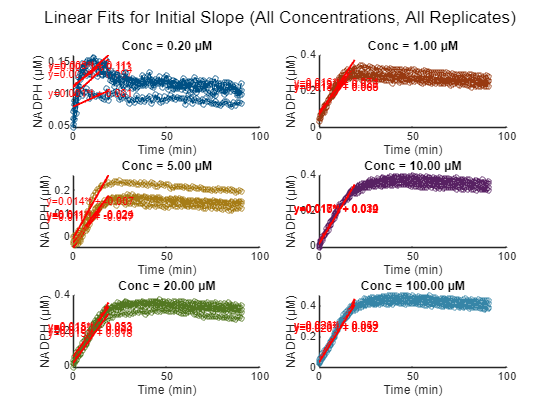



%% 3) SUBPLOTS SHOWING LINEAR FIT FOR EARLY POINTS
figure('Name','Initial Slope Fits by Concentration');
numRows = ceil(sqrt(numConcs));
numCols = ceil(numConcs / numRows);

cIndex = 1;
for c = 1:numConcs
    subplot(numRows, numCols, cIndex);
    cIndex = cIndex + 1;
    hold on;
    
    colStart  = (c-1)*replicateCount + 1;
    colEnd    = c*replicateCount;
    theseCols = colStart:colEnd;
    
    concLabel = concentrations_in_header(colStart);  % use the first col as label
    thisColor = colors(c,:);
    
    for r = 1:replicateCount
        repCol    = theseCols(r);
        singleRep = NADPHData(:, repCol);
        
        % Full replicate
        plot(time, singleRep, 'o-', 'Color', 0.7*thisColor, 'MarkerSize', 4);
        
        % Fit only first few points
        init_t   = time(1:num_pts_for_initial_slope);
        init_f   = singleRep(1:num_pts_for_initial_slope);
        p        = polyfit(init_t, init_f, 1);
        
        tFit = linspace(init_t(1), init_t(end), 50);
        fFit = polyval(p, tFit);
        
        plot(tFit, fFit, 'r-', 'LineWidth', 1.5);
        
        % Optionally annotate slope/intercept
        eqnStr = sprintf('y=%.3f*t + %.3f', p(1), p(2));
        text(tFit(round(end/2)), fFit(round(end/2)), eqnStr, ...
            'Color','r','FontSize',8,'HorizontalAlignment','center',...
            'VerticalAlignment','bottom');
    end
    
    title(sprintf('Conc = %.2f µM', concLabel));
    xlabel('Time (min)');
    ylabel('NADPH (µM)');
    hold off;
end
sgtitle('Linear Fits for Initial Slope (All Concentrations, All Replicates)');

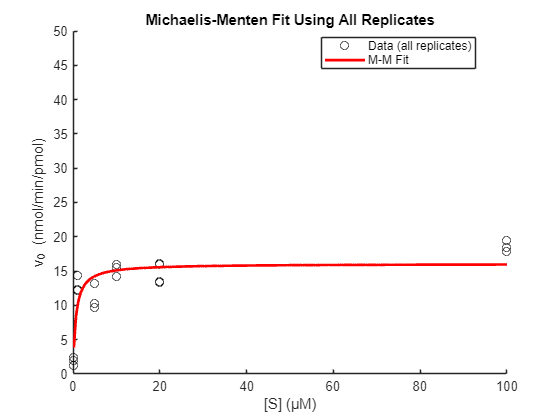



%% 4) FIT MICHAELIS-MENTEN (ALL REPLICATES)
% We have all_Conc (µM) and all_v0_converted (nmol/min/pmol)

valid_idx = ~isnan(all_Conc) & ~isnan(all_v0_converted);
S_data    = all_Conc(valid_idx);
v_data    = all_v0_converted(valid_idx);

% M-M model: v = (Vmax * S) / (Km + S)
michaelis_menten = @(params, S) (params(1).*S) ./ (params(2) + S);

% Good initial guesses
Vmax_guess = max(v_data);
Km_guess   = mean(S_data);
init_params= [Vmax_guess, Km_guess];

% Use lsqcurvefit from Optimization Toolbox
options = optimoptions('lsqcurvefit','Display','off');
[fitted_params, ~, residual, exitflag, ~, ~, jacobian] = lsqcurvefit( ...
    michaelis_menten, init_params, S_data, v_data, [], [], options);

if exitflag <= 0
    warning('Michaelis-Menten fit may not have converged (exitflag=%d).', exitflag);
end

Vmax = fitted_params(1);   % nmol/min/pmol
Km   = fitted_params(2);   % µM

% Plot final M-M fit
figure('Name','Michaelis-Menten Fit');
hold on;
plot(S_data, v_data, 'bo', 'Color','k', 'DisplayName','Data (all replicates)');
S_fit = linspace(min(S_data), max(S_data), 200);
v_fit = michaelis_menten(fitted_params, S_fit);
plot(S_fit, v_fit, 'r-', 'LineWidth', 2, 'DisplayName','M-M Fit');
xlabel('[S] (µM)');
ylabel('v_0 (nmol/min/pmol)');
title('Michaelis-Menten Fit Using All Replicates');
legend('Location','best');
ylim([0,50]);
hold off;


% Compute R²
n = length(S_data);
p = 2;  % # params
df = n - p;
ss_res = sum(residual.^2);
ss_tot = sum((v_data - mean(v_data)).^2);
R2 = 1 - (ss_res/ss_tot);

% Compute 95% confidence intervals
residualVar = ss_res / df;   % MSE
J = full(jacobian);
covParams = residualVar * inv(J'*J);
paramSE = sqrt(diag(covParams)); % [SE(Vmax), SE(Km)]
tval = tinv(1 - alpha/2, df);

Vmax_CI = [Vmax - tval*paramSE(1), Vmax + tval*paramSE(1)];
Km_CI   = [Km   - tval*paramSE(2), Km   + tval*paramSE(2)];

% Print results
disp('=== Michaelis-Menten Fit Results ===');

=== Michaelis-Menten Fit Results ===


fprintf('  Vmax = %.4f nmol/min/pmol  (95%% CI: [%.4f, %.4f])\n', ...
    Vmax, Vmax_CI(1), Vmax_CI(2));

  Vmax = 16.0594 nmol/min/pmol  (95% CI: [14.4440, 17.6749])


fprintf('  Km   = %.4f µM            (95%% CI: [%.4f, %.4f])\n', ...
    Km, Km_CI(1), Km_CI(2));

  Km   = 0.6314 µM            (95% CI: [0.2351, 1.0277])


fprintf('  R²   = %.4f\n', R2);

  R²   = 0.7798


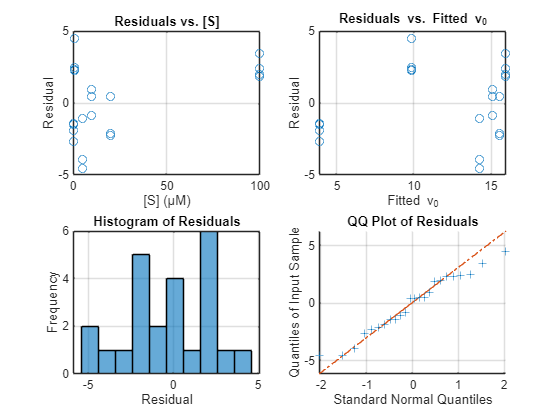


%% 5) RESIDUAL ANALYSIS (no System ID Toolbox needed)
% Residuals = observed - predicted
v_pred = michaelis_menten(fitted_params, S_data);
mm_residuals = v_data - v_pred;

% Plot residuals vs. substrate concentration
figure('Name','Residual Analysis - Michaelis-Menten');

subplot(2,2,1);
plot(S_data, mm_residuals, 'o');
xlabel('[S] (µM)');
ylabel('Residual');
title('Residuals vs. [S]');
grid on;

% Residuals vs. fitted values
subplot(2,2,2);
plot(v_pred, mm_residuals, 'o');
xlabel('Fitted v_0');
ylabel('Residual');
title('Residuals vs. Fitted v_0');
grid on;

% Histogram of residuals
subplot(2,2,3);
histogram(mm_residuals, 10); % e.g., 10 bins
xlabel('Residual');
ylabel('Frequency');
title('Histogram of Residuals');
grid on;

% QQ plot (requires Statistics and Machine Learning Toolbox)
subplot(2,2,4);
qqplot(mm_residuals);
title('QQ Plot of Residuals');
grid on;